## ANALYSIS OF MORE THAN 1 SAMPLE

GENERATE DIFFERENT OBJECTS FOR THE DIFFERENT SAMPLES

1st sample is added and included in SPOTS1 for GBM organoids

decoded_file = 'G:\Analysis_of_samples\JESSICA_CANCER_190320\2805_2_QT_0.4_0.001_details.csv';
image = 'G:\Analysis_of_samples\JESSICA_CANCER_190320\2_DAPI.tif';    % important for size
scale=1; %
%% do not modify
% load
SPOTS1=ISS_getspots(decoded_file);
SPOTS1.image=image;
SPOTS1.scale=scale;
SPOTS1.output_directory='G:\Analysis_of_samples\JESSICA_CANCER_190320\outputfolder'; %YOU CAN MODIFY THIS MAYBE
mkdir(SPOTS1.output_directory);

Addding the second file in SPOTS2

decoded_file = 'G:\Analysis_of_samples\JESSICA_CANCER_190320\2805_5_QT_0.4_0.001_details.csv';
image = 'G:\Analysis_of_samples\JESSICA_CANCER_190320\5_DAPI.tif';    % important for size
scale=1;
%% do not modify
% load
SPOTS2=ISS_getspots(decoded_file);
SPOTS2.image=image;
SPOTS2.scale=scale;
SPOTS2.output_directory='G:\Analysis_of_samples\JESSICA_CANCER_190320';
mkdir(SPOTS2.output_directory);

Addding the second file in SPOTS3

decoded_file = 'G:\Analysis_of_samples\JESSICA_CANCER_190320\2805_7_QT_0.3_0.003_details.csv';
image = 'G:\Analysis_of_samples\JESSICA_CANCER_190320\7_DAPI_50.tif';    % important for size
scale=0.5;
%% do not modify
% load
SPOTS3=ISS_getspots(decoded_file);
SPOTS3.image=image;
SPOTS3.scale=scale;
SPOTS3.output_directory='G:\Analysis_of_samples\JESSICA_CANCER_190320';
mkdir(SPOTS3.output_directory);

**IN CASE YOU NEED MORE SAMPLES, YOU CAN COPY THE CHUNK OF CODE THAT YOU HAVE JUST RAN CHANGE SPOTS3 by SPOTS4,SPOTS...**

And then we combine them into a big object (note that if you have added more samples you need to add them here as well)

ALLSPOTS.SPOTS1=SPOTS1;
ALLSPOTS.SPOTS2=SPOTS2;
ALLSPOTS.SPOTS3=SPOTS3;

## Creating overlapping means

We do capture the expression of different regions in the tissue by binning it and capturing the expression profile. In this case *OverlappingBins* generates bins that overlap between them. In this case, we can specify on 2nd position distance between spots in pixels and on 3rd position the radius of the bin

distance=600;
radius=600;
ALLEXPRESSION=ISS_OverlappingBins_moresamples(ALLSPOTS,distance,radius)

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



ALLEXPRESSION = struct with fields:
           exp: [8054×54 double]
           loc: [8054×2 double]
      genename: {54×1 cell}
    hexbinsize: 180
        sample: [8054×1 double]
         image: {'G:\Analysis_of_samples\JESSICA_CANCER_190320\2_DAPI.tif'  'G:\Analysis_of_samples\JESSICA_CANCER_190320\5_DAPI.tif'  'G:\Analysis_of_samples\JESSICA_CANCER_190320\7_DAPI_50.tif'}
         scale: {[1]  [1]  [0.5000]}


### **Tsne representation **

In order to represent the heterogeneity in a tissue, we use binned or segmented data to perform 3D tSNE, representing each of the dimensions in RGB scale. Therefore, we are able to represent differentially expressed regions. We can select the genes going into the analysis

genes = 54×1 cell array
    {'ACTB'       }
    {'AMZ1mut'    }
    {'AMZ1wt'     }
    {'AP3B22mut'  }
    {'AP3B22wt'   }
    {'ARHGEF28mut'}
    {'ARHGEF28wt' }
    {'CCDC105mut' }
    {'CCDC105wt'  }
    {'CKAP5mut'   }
    {'CKAP5wt'    }
    {'CREBBPmut'  }
    {'CREBBPwt'   }
    {'DENND1Amut' }
    {'DENND1Awt'  }
    {'DSELmut'    }
    {'DSELwt'     }
    {'EMILIN2mut' }
    {'EMILIN2wt'  }
    {'FGFR1exp'   }
    {'FGFR1expNew'}
    {'FZD4mut'    }
    {'FZD4wt'     }
    {'KCNT1mut'   }
    {'KCNT1wt'    }
    {'KIAA0652mut'}
    {'KIAA0652wt' }
    {'KIF14mut'   }
    {'KIF14wt'    }
    {'LRP1Bmut'   }


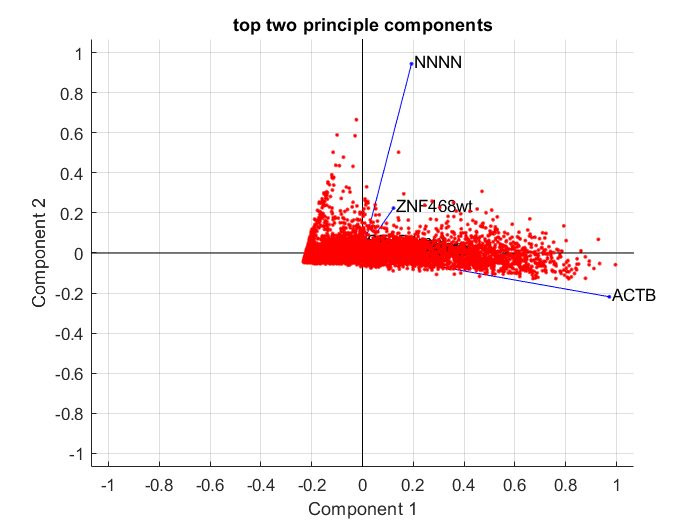


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    2.295038e+01 |    2.087695e-03 |
|       40 |    1.760356e+01 |    1.747923e-03 |
|       60 |    1.714202e+01 |    5.818921e-04 |
|       80 |    1.687879e+01 |    6.663026e-04 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    2.789747e+00 |    3.047575e-04 |
|      120 |    2.148659e+00 |    5.206070e-05 |
|      140 |    1.846786e+00 |    4.072368e-05 |
|      160 |    1.673927e+00 |    4.197580e-05 |
|      180 |    1.567066e+00 |    3.989773e-05 |
|      200 |    1.497059e+00 |    3.290936e-05 |
|      220 |    1.

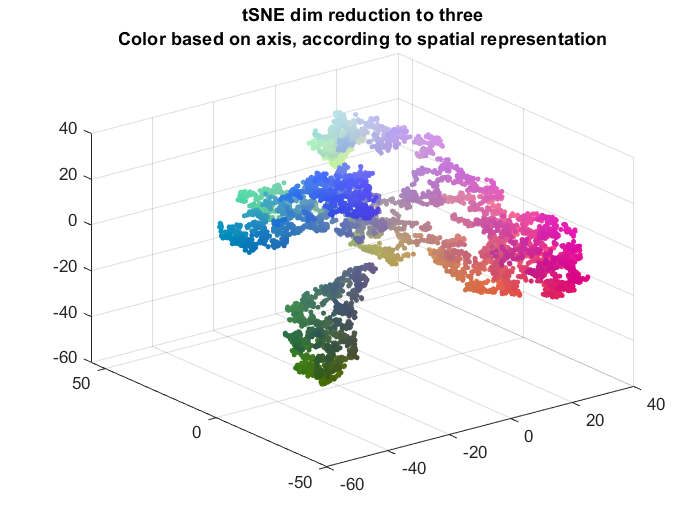

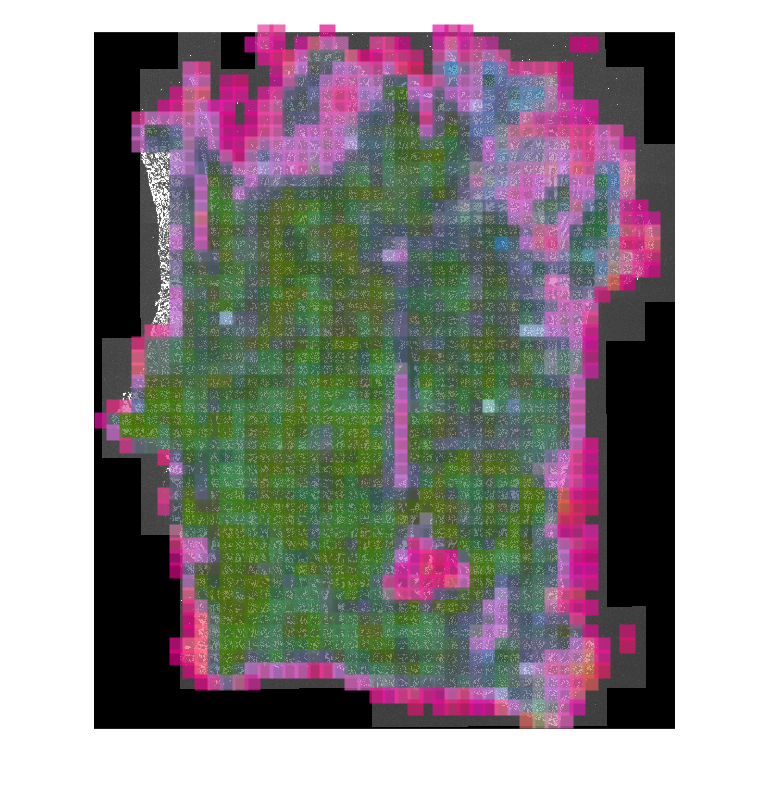

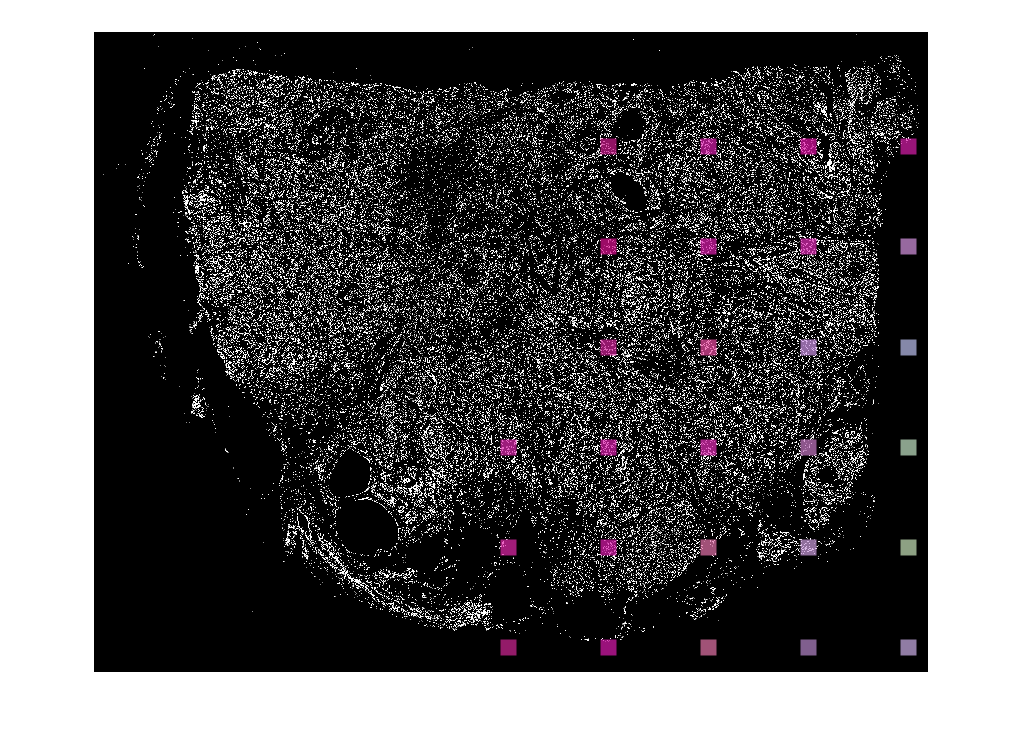

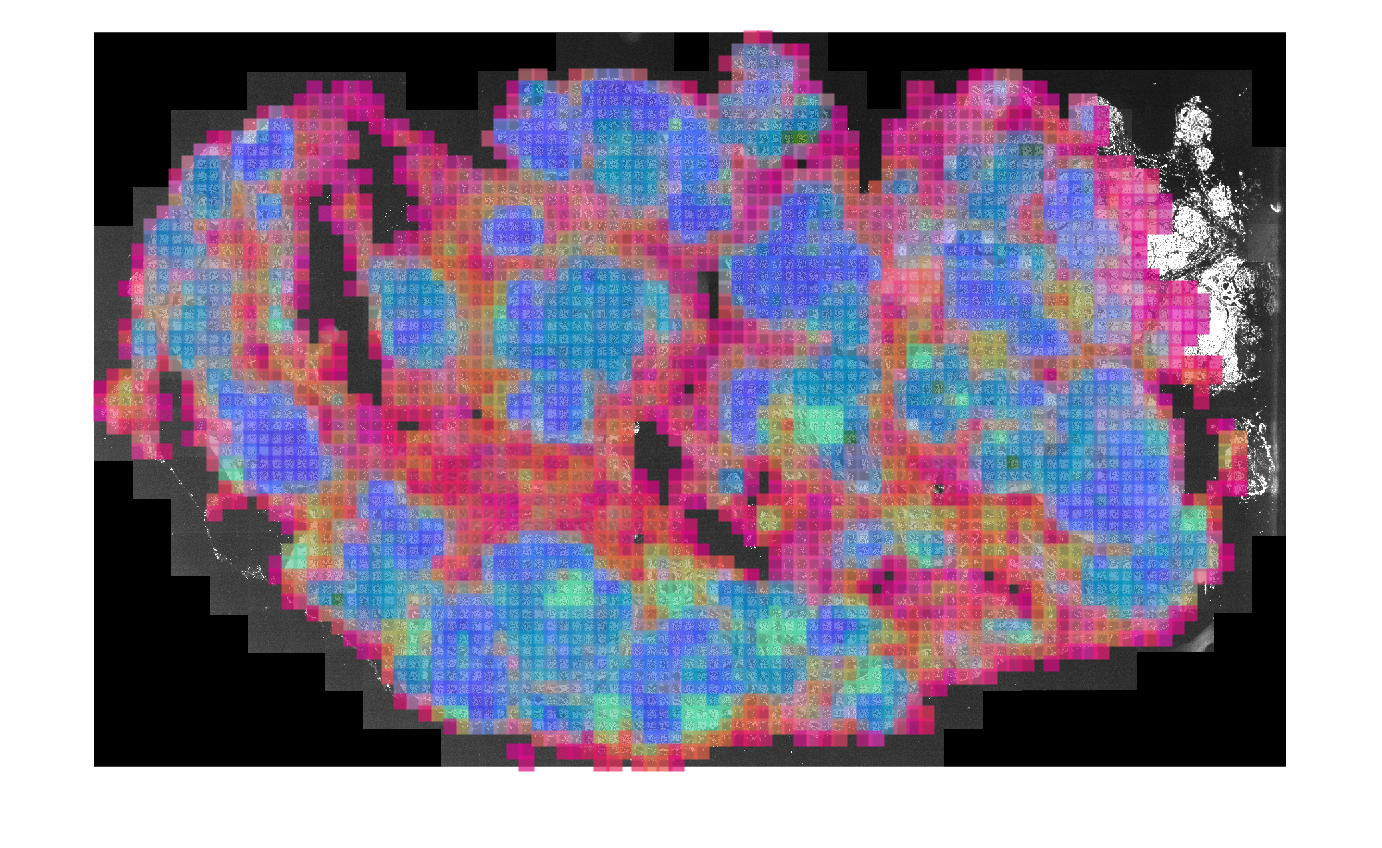

ISS_tsneRGB_several_samples(ALLEXPRESSION,ALLSPOTS.SPOTS1,10)

## Hierarchical clustering data

Hierarchical custering performs a clustering based on a hierarchical strategy, by dividing data in binary categories consecutively. In this case, the number of categories desired needs to be specified by the user.

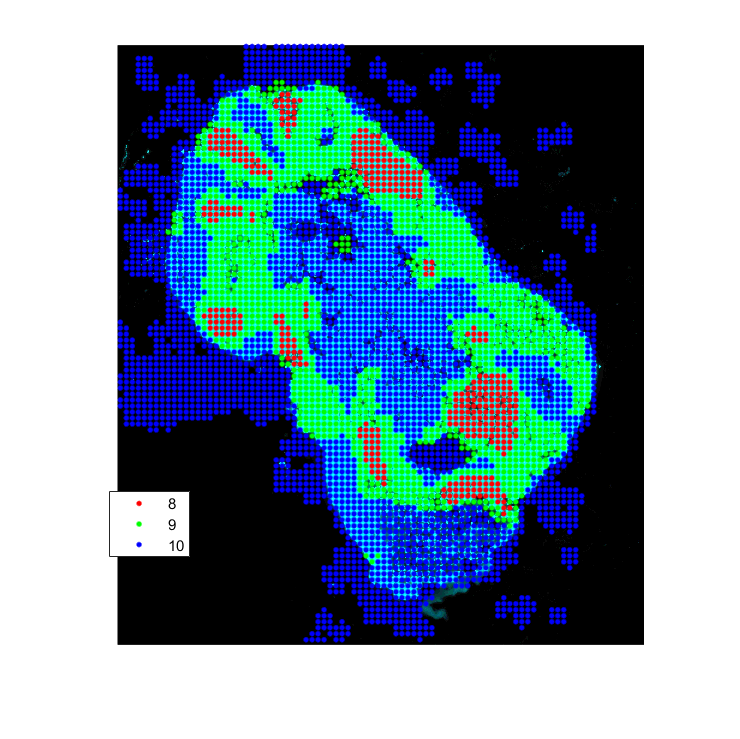

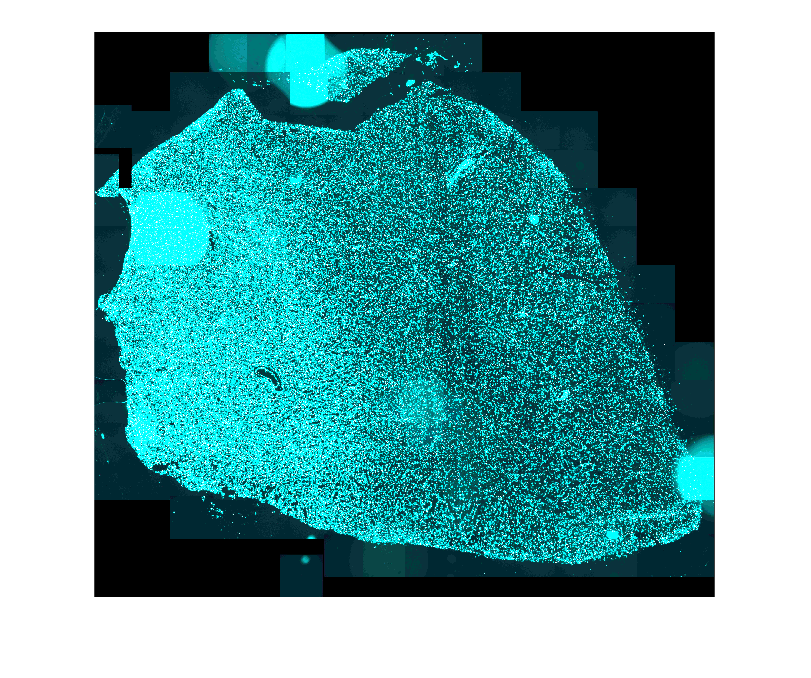

ALLCELLS = struct with fields:
    sample1: [1×1 struct]
    sample2: [1×1 struct]


[ALLCELLS]=ISS_hierarchical_clustering_several(ALLEXPRESSION,SPOTS1,10)

UNDER CONSTRUCTION

BI=ISS_Enviroment_neighbors_moresamples(SUPEROBJECT,radius)

     1

     1

     1

     1



BI = struct with fields:
           exp: [4×105 double]
           loc: [4×2 double]
      genename: {105×1 cell}
    hexbinsize: 6
        sample: [4×1 double]
         image: {'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'  'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'  'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'  'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'}
         scale: {[1]  [1]  [1]  [1]}
